parallel = readmatrix("C:\Users\avall\OneDrive\Desktop\Tuesday 10-12\20211012_angleExperiment\parallel.csv");
perpendicular = readmatrix("C:\Users\avall\OneDrive\Desktop\Tuesday 10-12\20211012_angleExperiment\perpendicular.csv");

e_std_par = parallel(1:4801,8)';
n_std_par = parallel(1:4801,9)';
u_std_par = parallel(1:4801,10)';

e_std_perp = perpendicular(1:4801,8)';
n_std_perp = perpendicular(1:4801,9)';
u_std_perp = perpendicular(1:4801,10)';

n = 0:0.1:480;
figure()
sz=1

sz = 1

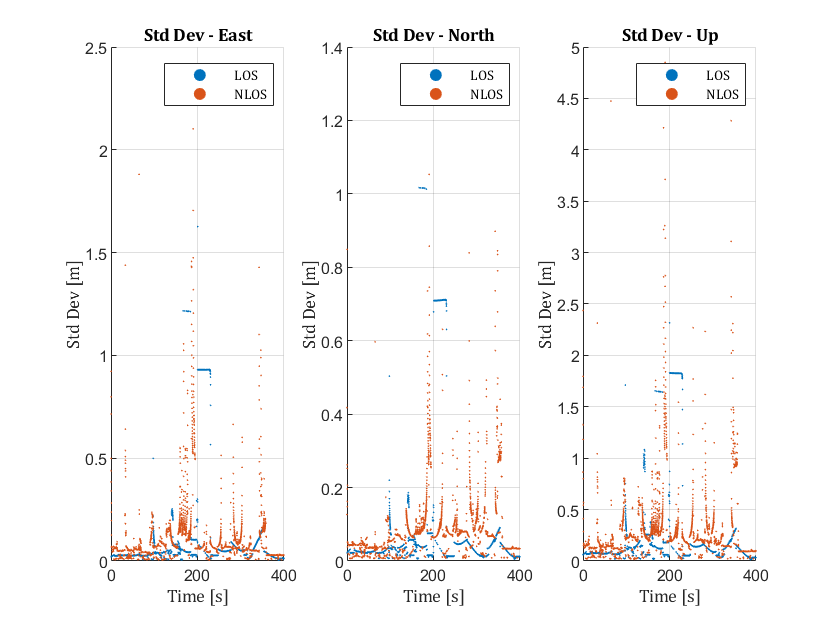

subplot(1,3,1)
scatter(n,e_std_par, sz, 'filled')
hold on
scatter(n,e_std_perp, sz, 'filled')
hold on
xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'Std Dev [m]'},'FontSize',8,'FontName','Cambria');
title({'Std Dev - East'},'FontWeight','bold','FontSize',10,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =8; 
legend({'LOS','NLOS'},'FontSize',7,'FontName','Cambria')

xlim([0 400])

subplot(1,3,2)
scatter(n,n_std_par, sz, 'filled')
hold on
scatter(n,n_std_perp, sz, 'filled')
hold on
xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'Std Dev [m]'},'FontSize',8,'FontName','Cambria');
title({'Std Dev - North'},'FontWeight','bold','FontSize',10,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =8; 
legend({'LOS','NLOS'},'FontSize',7,'FontName','Cambria')
xlim([0 400])

subplot(1,3,3)
scatter(n,u_std_par, sz, 'filled')
hold on
scatter(n,u_std_perp, sz, 'filled')
xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'Std Dev [m]'},'FontSize',8,'FontName','Cambria');
title({'Std Dev - Up'},'FontWeight','bold','FontSize',10,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =8; 
legend({'LOS','NLOS'},'FontSize',7,'FontName','Cambria')
xlim([0 400])

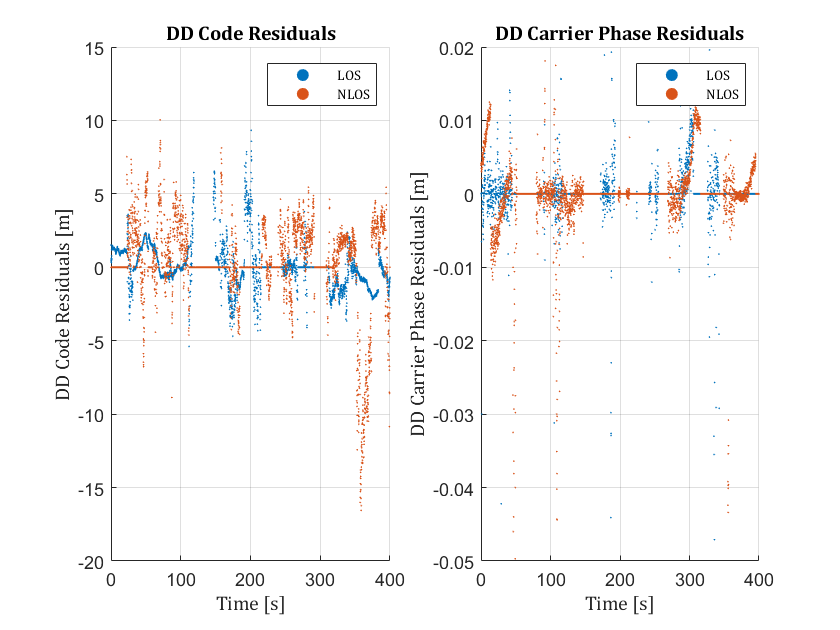


%% LOS VS NLOS

parallel_res = readmatrix("C:\Users\avall\OneDrive\Desktop\g26_par.xlsx");
perpendicular_res = readmatrix("C:\Users\avall\OneDrive\Desktop\g26_perp.xlsx");

%parallel_res = readmatrix("C:\Users\avall\OneDrive\Desktop\parResiduals.xlsx");
%perpendicular_res = readmatrix("C:\Users\avall\OneDrive\Desktop\perpRes.xlsx");


res_par_code = parallel_res(1:4000,4)';
res_perp_code = perpendicular_res(1:4000,4)';

res_par_phase= parallel_res(675:4674,5)';
res_perp_phase = perpendicular_res(675:4674,5)';

sz = 1;
n=0:0.1:399.9;

figure()
subplot(1,2,1)
scatter(n,res_par_code, sz, 'filled')
hold on
scatter(n,res_perp_code, sz, 'filled')
hold on
% general plot setup
xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'DD Code Residuals [m]'},'FontSize',8,'FontName','Cambria');
title({'DD Code Residuals'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'LOS','NLOS'},'FontSize',7,'FontName','Cambria')

subplot(1,2,2)
scatter(n,res_perp_phase, sz, 'filled')
hold on
scatter(n,res_par_phase, sz, 'filled')
hold on
% general plot setup
xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'DD Carrier Phase Residuals [m]'},'FontSize',8,'FontName','Cambria');
title({'DD Carrier Phase Residuals'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
ylim([-0.05 0.02])
legend({'LOS','NLOS'},'FontSize',7,'FontName','Cambria')